PID 2DOF

autor: Klysm.

Com base no video https://www.youtube.com/watch?v=bubN1CXBMUM

Exemplo 3

Projetar um controlador PID 2DOF com as características:

$t_s < 5;$ $mp < 10$%; $t_{s,d} < 1$; $mp_d < 5$%;

$G(s) = \frac{(s+5)}{s(s+1)(s+2)}$.

Solução:


$$K = 1;$$


$A(s) = (s+5)$;  numerador da tf da planta

$B(s) = s^3 + 3s^2 +2s$;  denominador da tf da planta

$\frac{Y(s)}{R(s)} = \frac{(y_1 s^2 + a_1 s + b_1) K} {sB(s) + (y s^2 + a s + b)K}$;

onde:

$y = y_1 + y_2$, $a = a_1+a_2$ e $b=b_1+b_2$;


$$\frac{Y(s)}{R(s)} = \frac{(y_1 s^2 + a_1 s + b_1)1} {s^4 + 3s^3 + 2s^2 + (y s^2 + a s + b)1};$$



$$\frac{Y(s)}{R(s)} = \frac{y_1 s^2 + a_1 s + b_1} {s^4 + 3s^3 + (2 + y_1 + y_2)s^2 + (a_1 + a_2) s + (b_1 + b_2)}.$$


Utilizando de alocação de zeros, casa-se os coeficientes do polinômio 

quadrático do numerador com o do denominador. Então:


$$a_0 \to y_1=(2+y_1+y_2) \to y_2 = -2;$$



$$a_1 \to a_1=(a_1+a_2) \to a_2 = 0;$$


$a_2 \to b_1=(b_1+b_2) \to b_2 = 0$.

Como o controlador está em série com um filtro, sendo o filtro $\frac{1}{A(s)}$, assim:

$G_{c2} = \frac{-2 s^2}{s(s+5)}$, sendo basicamente um $D = \frac{K_d s^2}{s}$.

Encontrado G_{c2}, agora, deve-se calcular G_{c1},

por meio de solução computacional.

Como possui eq.característica de grau 4, deve-se alocar os polos.

Malha fechada:


$$G_{yr} = \frac{a_0 s^2 + a_1 s + a_2}{s^4 + 3s^3 + a_0 s^2 + a_1 s + a_2}$$



$$P(s) = (s+a+bi)(s+a-bi)(s+c)(s+c)$$



$$P(s) = (a^2c^2 + b^2c^2) + (2a^2c + 2ac^2 + 2b^2c)s + (a^2 + 4ac + b^2 + c^2)s^2 + (2a + 2c)s^3 + s^4$$



$$P(s) = s^4 + 3s^3 + a_0 s^2 + a_1 s + a_2$$


Evita-se $c$ igual a zero, por não querer integrador duplo, e também $a$ igual a zero, pois necessita de amortecimento.

Assim, $3 = 2(a+c) \to a+c=3/2 \to a=3/2-c$.

Portanto, $0<a<3/2$ ; $0<c<3/2$.

Assim, utiliza-se a solução computacional:

for (a = 0:0.1:3/2)

    c=3/2 - a

    for (b = 100:-1:0)

        Corpo programa

        if $t_s <= 5$ & $mp <= 10$ & $t_{sd} <=1$ & $mp_d <= 5%$

        end

    end

end

A(s) não influencia na entrada de referência. Vai influenciar em relação ao distúrbio. Nota-se que o overshoot muda.

CÓDIGO:

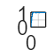

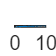

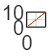

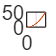

clc; clear; close all;

% EXEMPLO
% Projetar um controlador PID 2DOF
% ts < 0.5; mp < 10%; tsd < 0.1; mpd < 5%.

t = 0:0.1:10;   % vetor tempo
K = 1;          % ganho planta
ts = 5;         % tempo acomodacao aa referencia
tsd = 1;        % tempo acomodacao ao disturbio
mp = 10;        % sobressinal entrada referencia
mpd = 5;        % sobressinal entrada disturbio
stopC = 0.02;   % criterio parada
s = tf('s');    % operador Laplace
A = (s+5);      % numerador planta
u = 0;

for a=15:-0.2:0.2
    c=(3/2)-a;
    for b=100:-1:0.1
        % funcao transferencia Planta
        a0 = (a^2 + 4*a*c + b^2 + c^2);
        a1 = (2*a^2*c + 2*a*c^2 + 2*b^2*c);
        a2 = (a^2*c^2 + b^2*c^2);
        num = [a0 a1 a2];
        den = [1 (2*a + 2*c) a0 a1 a2];
        G = tf(num,den);

        y = step(G,t);
        m = (max(y)-1)*100;
        cont = size(y); % tamanho do vetor
        k1 = cont(1,1);

        while (abs(y(k1)-1))<stopC && k1>1 
        % permanece no loop ate chegar no criterio parada
            k1 = k1-1;
        % decrementa s e varre o conjunto dos sinais obtidos
        % ao aplicar o step de tras pra frente
        end

        Ts = t(1,k1); % transforma posicao do sinal em tempo.
        
        % DISTURBIO
        numd = [K 0];
        Gd = tf(numd,den)*A;
        D = step(Gd,t);
        md = max(D)*100;

        k1 = cont(1,1);

        while (D(k1)<stopC & k1>1)
            k1 = k1-1;
        end
        
        Tsd = t(1,k1); % transforma a posicao do sinal em tempo.
        
        if m<mp && Ts<ts && Tsd<tsd && md<mpd
            figure(1) % entrada em degrau sistema
            plot(t,y); grid;
            title('Entrada em degrau - sistema'); % Title of the plot
            xlabel('Time (s)');                   % X-axis label
            ylabel('Output (y)');                 % Y-axis label

            figure(2) % entrada em degrau disturbio
            plot(t,D); grid;
            title('Entrada em degrau - disturbio'); % Title of the plot
            xlabel('Time (s)');                     % X-axis label
            ylabel('Output (y)');                   % Y-axis label

            figure(3) % entrada em velocidade sistema
            u=step(1/(s),t);
            y=lsim(G,u,t);
            plot(t,y); grid;
            title('Entrada em velocidade');           % Title of the plot
            xlabel('Time (s)');                       % X-axis label
            ylabel('Output (y)');                     % Y-axis label

            hold on
            plot(t,u);
            grid;

            figure(4) % entrada em aceleracao
            u=step(1/(s*s),t);
            y=lsim(G,u,t);
            plot(t,y);
            title('Entrada em aceleracao');           % Title of the plot
            xlabel('Time (s)');                       % X-axis label
            ylabel('Output (y)'); 

            hold on
            plot(t,u);
            grid;

            u=1;
            sol_R = [a; b; c; m; Ts];
            sol_D = [md; Tsd];
            break;
        end % requisitos de controle
        
        if m<mp && Ts<ts && Tsd<tsd && md<mpd
            break;
        end
    end % for b

    if m<mp && Ts<ts && Tsd<tsd && md<mpd
            break;
    end
end % for a


if u == 1
    G = tf(num,den);
    sol_R
    sol_D
    gama1 = a0/K;
    alpha1 = a1/K;
    beta1 = a2/K;

    gama2 = -2;
    alpha2 = 0;
    beta2 = 0;

    num2 = [gama1 alpha1 beta1];
    den2 = [1 0];
    G2 = tf(num2,den2)/A;
    
    num3 = [gama2 alpha2 beta2];
    den3 = [1 0];
    G3 = tf(num3,den3)/A;
end

sol_R =     1.4000
   64.0000
    0.1000
    4.1284
    2.7000


sol_D =     0.4489
         0


('Acabou')

ans = 'Acabou'